# **Assignment:  Feature Extraction of CWRU Dataset**

**Name: Gyeonheal An**

## **Instruction**

1. **Read the paper and understand the whole process**

This Assignment is implementation a part of Feature Extration in  the literature 

[Download here](https://github.com/ykkimhgu/HGU_IAIA/tree/main/Docs)

- Rauber, T. W., de Assis Boldt, F., & Varejao, F. M. (2015, January). Heterogeneous Feature Models and Feature Selection Applied to Bearing Fault Diagnosis. *IEEE Transactions on Industrial Electronics*. Institute of Electrical and Electronics Engineers (IEEE).

**2. Extract and Analyze  Features**

**3. Compare  Features among different classes**

**Other reference**

Diagnostics 101: A Tutorial for Fault Diagnostics of Rolling Element Bearing Using Envelope Analysis in MATLAB 

[Matlab code]: [https://www.kau-sdol.com/matlab-code](https://www.kau-sdol.com/matlab-code)

## Dataset

**A sample of selected  CWRU bearing dataset **

- 1 data file for each fault state under specific condition

Download a selected sample of  CWRU Dataset ([**download here**](https://github.com/ykkimhgu/HGU_IAIA/tree/main/Dataset/CWRU_selected_dataset))

- Download   **Raw_data.zip**  

- `/Dataset/CWRU_selected_dataset/Raw_data/`

It should be located in your local folder of

- `/Dataset/CWRU_selected_dataset/Raw_data/`

Sampling: 

- **Drive end bearing(12K): 12,000 samples/second**

Classes:

- Normal / Outer Race fault / Inner Race fault

- Each under 1HP load,  fault diameter of 0.007inches

Variables

- DE - drive end accelerometer data

- FE - fan end accelerometer data

- BA - base accelerometer data

- time - time series data

- RPM - shaft rpm during testing

### Drive End Bearing Experiment- 12K

## 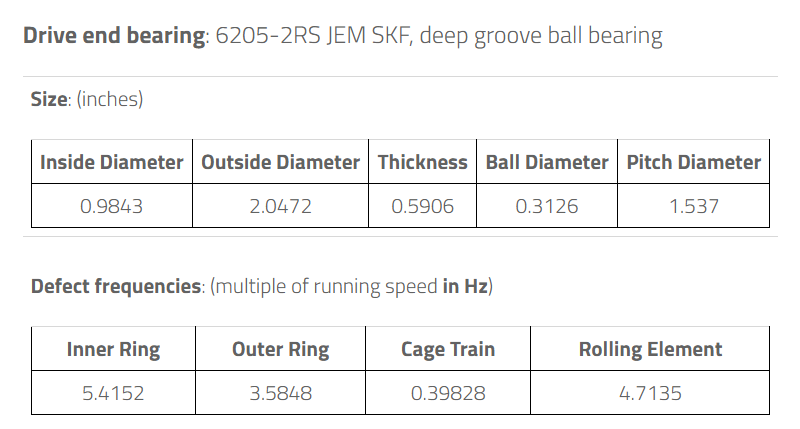

## Introduction

Analytical Signal in Frequency-Domain approach, using Envelop Extraction

addpath('../../Library')

## Load Dataset

close all; clear; clc;

addpath("../../Dataset/CWRU_selected_dataset/Raw_data")


load('ball_007_1hp.mat') %X119
load('inner_007_1hp.mat') %X106
load('normal_1hp.mat') %X098
load('outer_007_1hp.mat') %X131

## **Preprocessing**

- Ballpass frequency, outer race (BPFO)


$$BPFO = \frac{nf_r}{2}\left(1-\frac{d}{D}\cos \phi\right)$$


- Ballpass frequency, inner race (BPFI)


$$BPFI = \frac{nf_r}{2}\left(1+\frac{d}{D}\cos \phi\right)$$


- Fundamental train frequency (FTF), also known as cage speed


$$FTF = \frac{f_r}{2}\left(1-\frac{d}{D}\cos \phi\right)$$


- Ball (roller) spin frequency


$$BSF = \frac{D}{2d}\left[1-\left(\frac{d}{D}\cos \phi\right)^2\right]$$


%%% YOUR CODE GOES HERE
fs = 12000;

fr_inner = X106RPM*(2*pi)/60.0;
fr_outer = X131RPM*(2*pi)/60.0;

BPFO_freq = 3.5848 * X131RPM / 60;
BPFI_freq = 5.4152 * X106RPM / 60;
BPFB_freq = 4.7135 * X119RPM / 60;

L_BALL = length(X119_DE_time);
L_INNER = length(X106_DE_time);
L_NORMAL = length(X098_DE_time);
L_OUTER = length(X131_DE_time);

## **Features Extraction**

• Extract Time-Domain Features

- Mean, Std, Skewness, Kurtosis, Peak2Peak, RMS, CrestFactor,  ShapeFactor, ImpulseFactor, MarginFactor, Energy etc

• Extract Frequency-Domain Features

-   Basic features,  SKMean, SKStd, SKSkewness, SKKurtosis, etc

• Envelop Extraction

• Plot  STFT 

• Plot  Kurtogram

• Analyze Spectral Kurtosis

### **1. Extract Time-Domain Features**

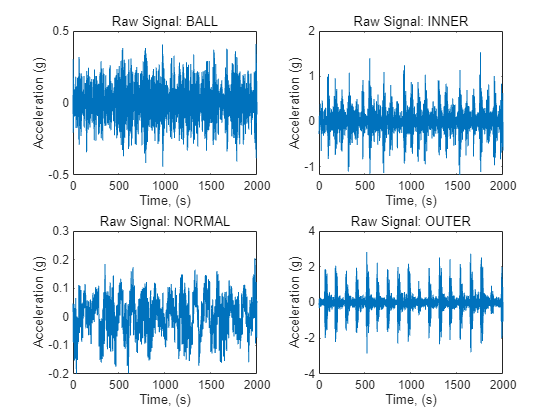

figure
subplot(2, 2, 1);
plot(X119_DE_time(1:2000));
xlabel('Time, (s)');
ylabel('Acceleration (g)');
title('Raw Signal: BALL');
hold on;

subplot(2,2,2);
plot(X106_DE_time(1:2000));
xlabel('Time, (s)');
ylabel('Acceleration (g)');
title('Raw Signal: INNER');

hold on;
subplot(2,2,3);
plot(X098_DE_time(1:2000));
xlabel('Time, (s)');
ylabel('Acceleration (g)');
title('Raw Signal: NORMAL');

hold on;
subplot(2,2,4);
plot(X131_DE_time(1:2000));
xlabel('Time, (s)');
ylabel('Acceleration (g)');
title('Raw Signal: OUTER');

timeFeatures(X119_DE_time) % Ball timeFeatures

ans = 1×14 table
      mean         std        rms        sra         aav      energy     peak       ppv        if        sf        cf        mf         sk          kt  
    _________    _______    _______    ________    _______    ______    _______    ______    ______    ______    ______    ______    _________    ______

    0.0038918    0.13901    0.13907    0.094363    0.11122    2348.1    0.65965    1.2993    5.9312    1.2504    4.7433    6.9905    0.0074533    2.9638


timeFeatures(X106_DE_time) % Inner timeFeatures

ans = 1×14 table
      mean        std        rms        sra        aav      energy     peak      ppv        if        sf        cf        mf        sk         kt  
    ________    _______    _______    _______    _______    ______    ______    ______    ______    ______    ______    ______    _______    ______

    0.005801    0.29284    0.29289    0.16484    0.20764    10465     1.5808    2.9838    7.6131    1.4105    5.3973    9.5902    0.13043    5.5423


timeFeatures(X098_DE_time) % Normal timeFeatures

ans = 1×14 table
      mean        std         rms         sra         aav       energy     peak       ppv        if        sf        cf       mf         sk         kt  
    ________    ________    ________    ________    ________    ______    _______    ______    ______    ______    ______    _____    ________    ______

    0.012564    0.065152    0.066352    0.045547    0.053471    2130.4    0.34588    0.6634    6.4686    1.2409    5.2129    7.594    -0.17305    2.9306


timeFeatures(X131_DE_time) % Outer timeFeatures

ans = 1×14 table
      mean         std        rms        sra        aav      energy     peak      ppv        if        sf        cf        mf         sk        kt  
    _________    _______    _______    _______    _______    ______    ______    ______    ______    ______    ______    ______    ________    _____

    0.0040611    0.59194    0.59195    0.26626    0.36646    42898     3.1123    6.1242    8.4927    1.6153    5.2577    11.689    0.033401    7.595


## 2. Extract Frequency-Domain Features

T_BALL = (0:L_BALL) / fs;
T_INNER = (0:L_INNER) / fs;
T_NORMAL = (0:L_NORMAL) / fs;
T_OUTER = (0:L_OUTER) / fs;

fft_BALL = getFFT(X119_DE_time, L_BALL);
fft_INNER = getFFT(X106_DE_time, L_INNER);

fft_NORMAL = getFFT(X098_DE_time, L_NORMAL);

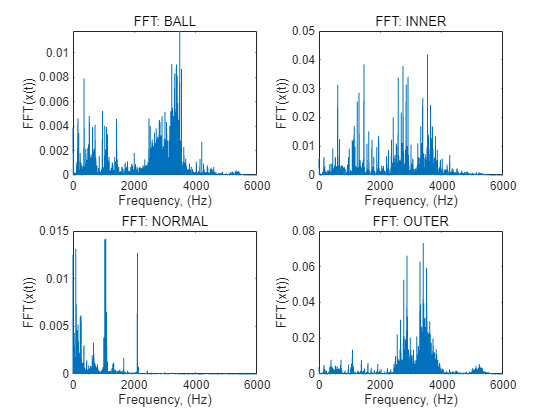

fft_OUTER = getFFT(X131_DE_time, L_OUTER);

f_BALL = 0:fs/L_BALL:fs/2;
f_INNER = 0:fs/L_INNER:fs/2;
f_NORMAL = 0:fs/L_NORMAL:fs/2;
f_OUTER = 0:fs/L_OUTER:fs/2;

figure
subplot(2, 2, 1);
plot(f_BALL, fft_BALL);
xlabel('Frequency, (Hz)');
ylabel('FFT(x(t))');
title('FFT: BALL');
hold on;

subplot(2,2,2);
plot(f_INNER, fft_INNER);
xlabel('Frequency, (Hz)');
ylabel('FFT(x(t))');
title('FFT: INNER');

hold on;
subplot(2,2,3);
plot(f_NORMAL, fft_NORMAL);
xlabel('Frequency, (Hz)');
ylabel('FFT(x(t))');
title('FFT: NORMAL');

hold on;
subplot(2,2,4);
plot(f_OUTER, fft_OUTER);
xlabel('Frequency, (Hz)');
ylabel('FFT(x(t))');
title('FFT: OUTER');

freqFeatures(fft_BALL)

ans = 1×3 table
        fc           rmsf          rvf    
    __________    __________    __________

    0.00013212    0.00039927    0.00037678


freqFeatures(fft_INNER)

ans = 1×3 table
        fc           rmsf          rvf    
    __________    __________    __________

    0.00025571    0.00083874    0.00079881


freqFeatures(fft_NORMAL)

ans = 1×3 table
        fc           rmsf          rvf    
    __________    __________    __________

    2.0723e-05    9.7079e-05    9.4841e-05


freqFeatures(fft_OUTER)

ans = 1×3 table
        fc          rmsf          rvf   
    __________    _________    _________

    0.00041833    0.0016918    0.0016393


## 3. Envelop Extraction

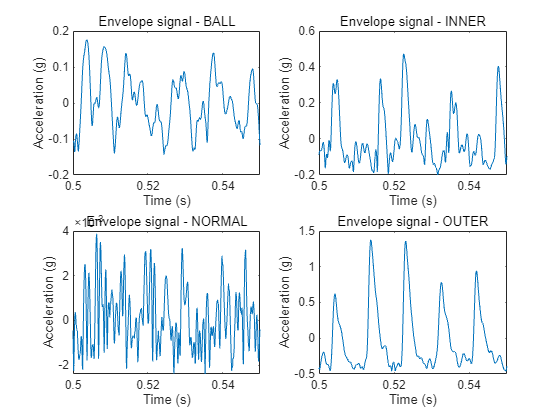

figure;

[pEnvBALL, fEnvBALL, xEnvBALL, tEnvBALL] = envspectrum(X119_DE_time, fs);
subplot(2, 2, 1);
plot(tEnvBALL, xEnvBALL);
xlim([0.5 0.55]);
xlabel('Time (s)')
ylabel('Acceleration (g)')
title('Envelope signal - BALL')

hold on;
[pEnvINNER, fEnvINNER, xEnvINNER, tEnvINNER] = envspectrum(X106_DE_time, fs);
subplot(2, 2, 2);
plot(tEnvINNER, xEnvINNER);
xlim([0.5 0.55]);
xlabel('Time (s)')
ylabel('Acceleration (g)')
title('Envelope signal - INNER')

hold on;
[pEnvNORMAL, fEnvNORMAL, xEnvNORMAL, tEnvNORMAL] = envspectrum(X098_DE_time, fs);
subplot(2, 2, 3);
plot(tEnvNORMAL, xEnvNORMAL);
xlim([0.5 0.55]);
xlabel('Time (s)')
ylabel('Acceleration (g)')
title('Envelope signal - NORMAL')

hold on;
[pEnvOUTER, fEnvOUTER, xEnvOUTER, tEnvOUTER] = envspectrum(X131_DE_time, fs);
subplot(2, 2, 4);
plot(tEnvOUTER, xEnvOUTER);
xlim([0.5 0.55]);
xlabel('Time (s)')
ylabel('Acceleration (g)')
title('Envelope signal - OUTER')

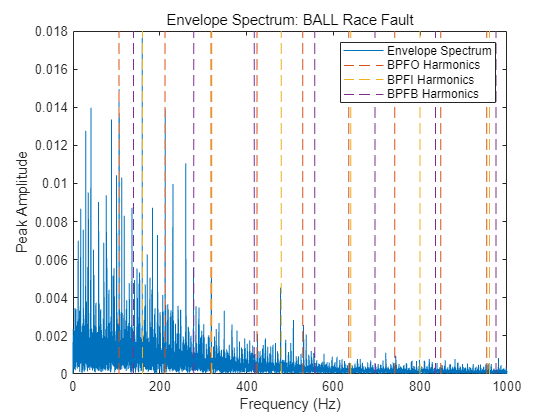

figure
plot(fEnvBALL, pEnvBALL)
xlim([0 1000])
ncomb = 10;
helperPlotCombs(ncomb, [BPFO_freq BPFI_freq BPFB_freq])
xlabel('Frequency (Hz)')
ylabel('Peak Amplitude')
title('Envelope Spectrum: BALL Race Fault')
legend('Envelope Spectrum', 'BPFO Harmonics','BPFI Harmonics', 'BPFB Harmonics')

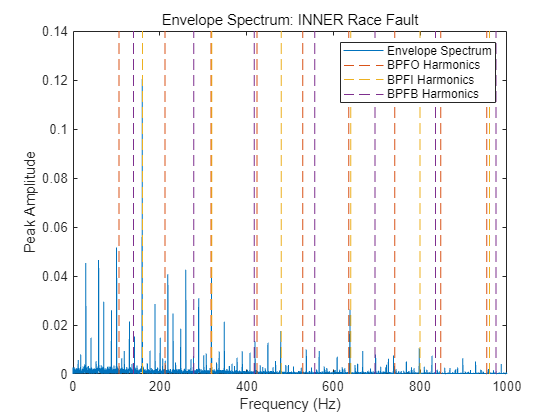

plot(fEnvINNER, pEnvINNER)
xlim([0 1000])
ncomb = 10;
helperPlotCombs(ncomb, [BPFO_freq BPFI_freq BPFB_freq])
xlabel('Frequency (Hz)')
ylabel('Peak Amplitude')
title('Envelope Spectrum: INNER Race Fault')
legend('Envelope Spectrum', 'BPFO Harmonics','BPFI Harmonics', 'BPFB Harmonics')

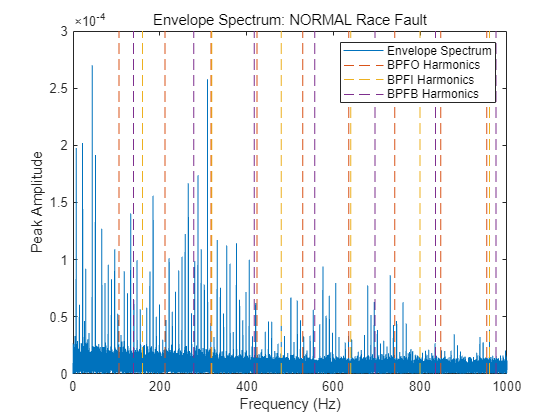

plot(fEnvNORMAL, pEnvNORMAL)
xlim([0 1000])
ncomb = 10;
helperPlotCombs(ncomb, [BPFO_freq BPFI_freq BPFB_freq])
xlabel('Frequency (Hz)')
ylabel('Peak Amplitude')
title('Envelope Spectrum: NORMAL Race Fault')
legend('Envelope Spectrum', 'BPFO Harmonics','BPFI Harmonics', 'BPFB Harmonics')

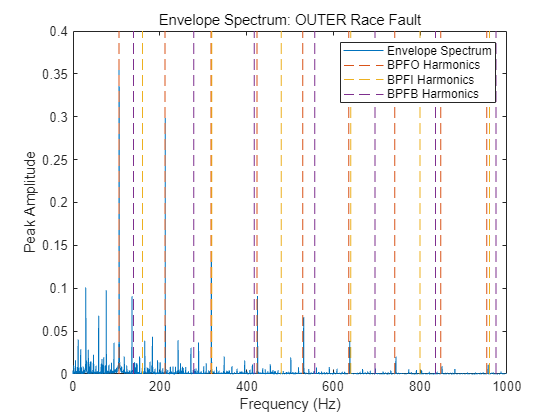

plot(fEnvOUTER, pEnvOUTER)
xlim([0 1000])
ncomb = 10;
helperPlotCombs(ncomb, [BPFO_freq BPFI_freq BPFB_freq])
xlabel('Frequency (Hz)')
ylabel('Peak Amplitude')
title('Envelope Spectrum: OUTER Race Fault')
legend('Envelope Spectrum', 'BPFO Harmonics','BPFI Harmonics', 'BPFB Harmonics')

## 4. Plot  STFT

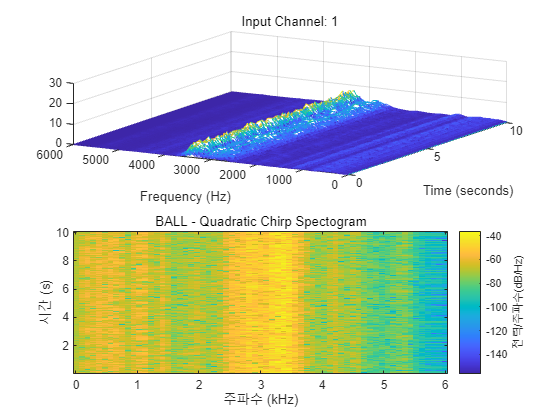

figure;
subplot(2,1,1);
[S,F,T] = stft(X119_DE_time,fs,Window=kaiser(128,5),OverlapLength=50,FFTLength=128, FrequencyRange = 'onesided');
waterfall(F,T,abs(S)')
helperGraphicsOpt(1)
hold on;
subplot(2,1,2);
spectrogram(X119_DE_time,128,50,128, fs)
title('BALL - Quadratic Chirp Spectogram')

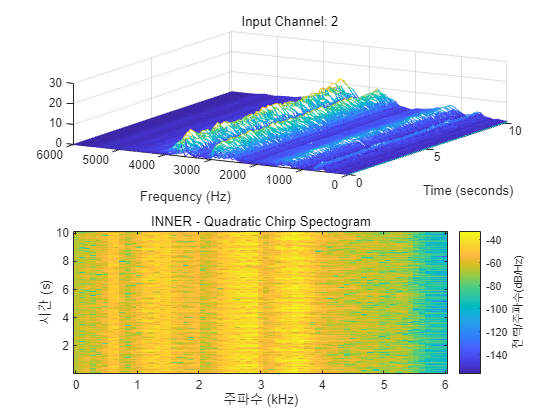

figure;
subplot(2,1,1);
[S,F,T] = stft(X106_DE_time,fs,Window=kaiser(128,5),OverlapLength=50,FFTLength=128, FrequencyRange = 'onesided');
waterfall(F,T,abs(S)')
helperGraphicsOpt(2)
hold on;
subplot(2,1,2);
spectrogram(X106_DE_time,128,50,128, fs)
title('INNER - Quadratic Chirp Spectogram')

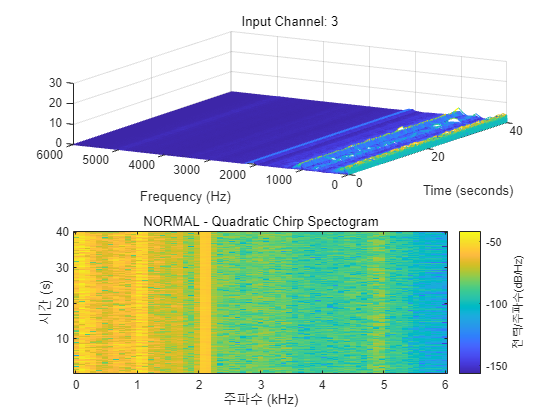

figure;
subplot(2,1,1);
[S,F,T] = stft(X098_DE_time,fs,Window=kaiser(128,5),OverlapLength=50,FFTLength=128, FrequencyRange = 'onesided');
waterfall(F,T,abs(S)')
helperGraphicsOpt(3)
hold on;
subplot(2,1,2);
spectrogram(X098_DE_time,128,50,128, fs)
title('NORMAL - Quadratic Chirp Spectogram')

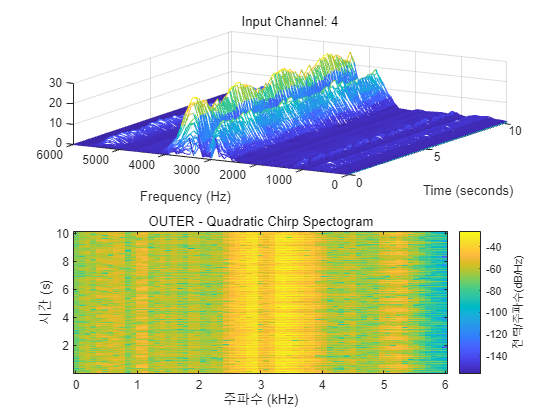

figure;
subplot(2,1,1);
[S,F,T] = stft(X131_DE_time,fs,Window=kaiser(128,5),OverlapLength=50,FFTLength=128, FrequencyRange = 'onesided');
waterfall(F,T,abs(S)')
helperGraphicsOpt(4)
hold on;
subplot(2,1,2);
spectrogram(X131_DE_time,128,50,128, fs)
title('OUTER - Quadratic Chirp Spectogram')

function helperGraphicsOpt(ChannelId)
ax = gca;
ax.XDir = 'reverse';
ax.ZLim = [0 30];
ax.Title.String = ['Input Channel: ' num2str(ChannelId)];
ax.XLabel.String = 'Frequency (Hz)';
ax.YLabel.String = 'Time (seconds)';
ax.View = [30 45];
end

## 5. Plot  Kurtogram

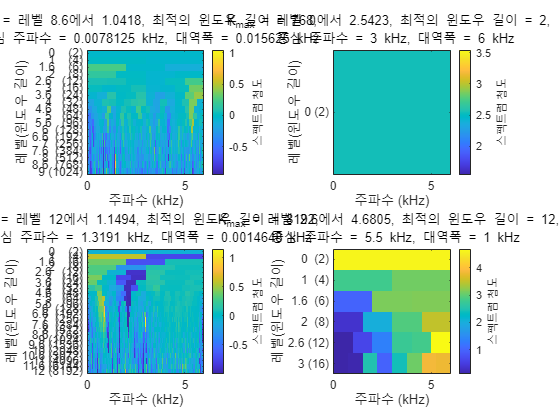

lv_BALL = 9; lv_INNER = 0; lv_NORMAL = 12; lv_OUTER = 3;

figure;
subplot(2,2,1);
kurtogram(X119_DE_time, fs, lv_BALL);

hold on;
subplot(2,2,2);
kurtogram(X106_DE_time, fs, lv_INNER);

hold on;
subplot(2,2,3);
kurtogram(X098_DE_time, fs, lv_NORMAL);

hold on;
subplot(2,2,4);
kurtogram(X131_DE_time, fs, lv_OUTER);

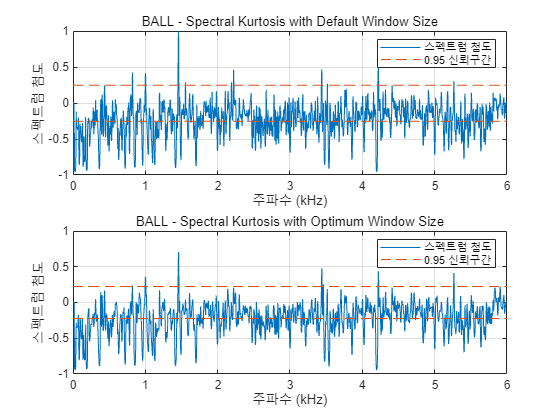

figure;
subplot(2,1,1);
pkurtosis(X119_DE_time, fs);
title('BALL - Spectral Kurtosis with Default Window Size')
hold on;
subplot(2,1,2);
[kgram_BALL,f_BALL,w_BALL,fc_BALL,wc_BALL,bw_BALL] = kurtogram(X119_DE_time, fs, lv_BALL);
pkurtosis(X119_DE_time,fs, wc_BALL)
title('BALL - Spectral Kurtosis with Optimum Window Size')

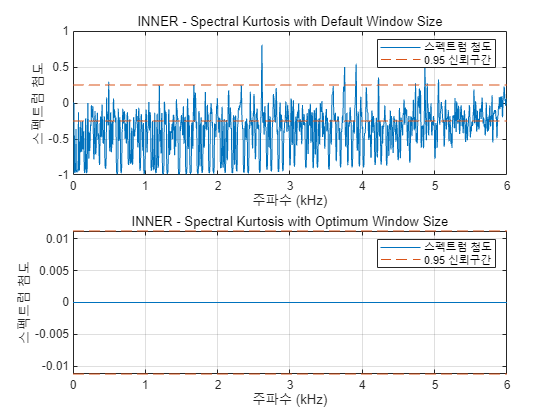

figure;
subplot(2,1,1);
pkurtosis(X106_DE_time, fs);
title('INNER - Spectral Kurtosis with Default Window Size')
hold on;
subplot(2,1,2);
[kgram_INNER,f_INNER,w_INNER,fc_INNER,wc_INNER,bw_INNER] = kurtogram(X106_DE_time, fs, lv_INNER);
pkurtosis(X106_DE_time,fs, wc_INNER)
title('INNER - Spectral Kurtosis with Optimum Window Size')

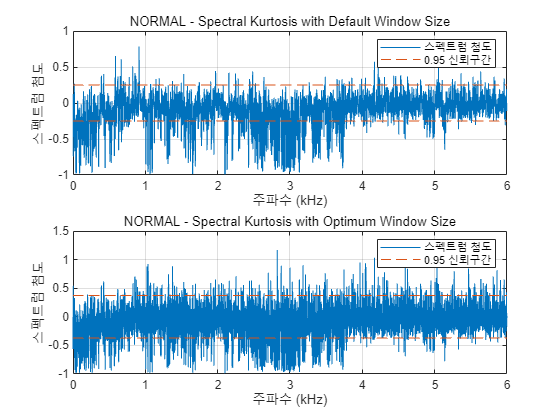

figure;
subplot(2,1,1);
pkurtosis(X098_DE_time, fs);
title('NORMAL - Spectral Kurtosis with Default Window Size')
hold on;
subplot(2,1,2);
[kgram_NORMAL,f_NORMAL,w_NORMAL,fc_NORMAL,wc_NORMAL,bw_NORMAL] = kurtogram(X098_DE_time, fs, lv_NORMAL);
pkurtosis(X098_DE_time,fs, wc_NORMAL)
title('NORMAL - Spectral Kurtosis with Optimum Window Size')

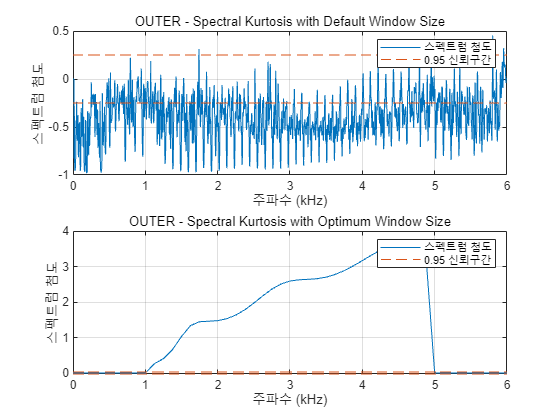

figure;
subplot(2,1,1);
pkurtosis(X131_DE_time, fs);
title('OUTER - Spectral Kurtosis with Default Window Size')
hold on;
subplot(2,1,2);
[kgram_OUTER,f_OUTER,w_OUTER,fc_OUTER,wc_OUTER,bw_OUTER] = kurtogram(X131_DE_time, fs, lv_OUTER);
pkurtosis(X131_DE_time,fs, wc_OUTER)
title('OUTER - Spectral Kurtosis with Optimum Window Size')

## **6. Apply Bandpass filter**

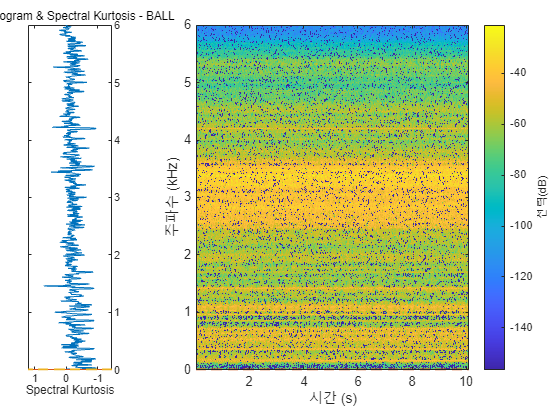

figure;
helperSpectrogramAndSpectralKurtosis(X119_DE_time, fs, lv_BALL)
title('Spectrogram & Spectral Kurtosis - BALL');

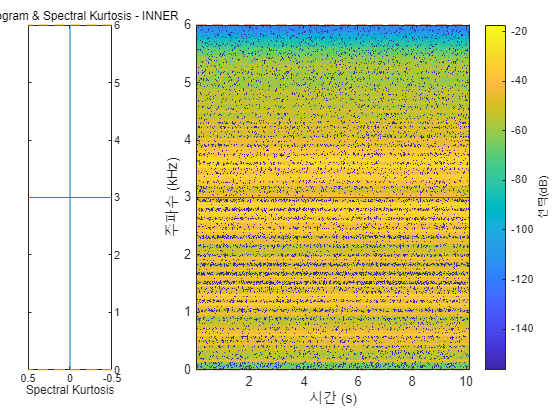

helperSpectrogramAndSpectralKurtosis(X106_DE_time, fs, lv_INNER)
title('Spectrogram & Spectral Kurtosis - INNER');

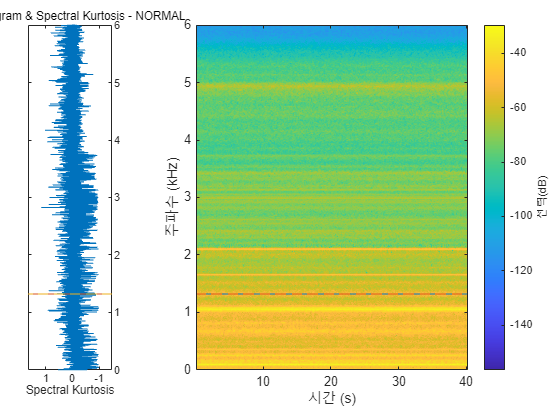

helperSpectrogramAndSpectralKurtosis(X098_DE_time, fs, lv_NORMAL)
title('Spectrogram & Spectral Kurtosis - NORMAL');

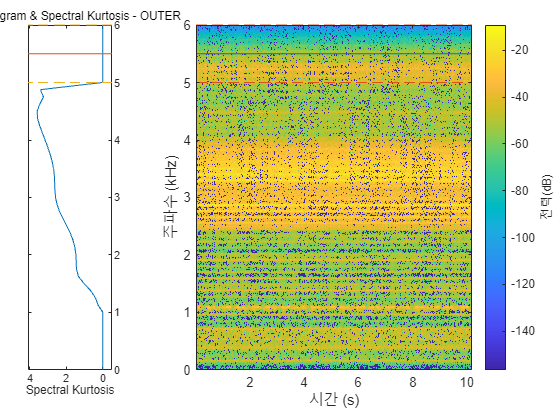

helperSpectrogramAndSpectralKurtosis(X131_DE_time, fs, lv_OUTER)
title('Spectrogram & Spectral Kurtosis - OUTER');

xNormal = X098_DE_time;
xBall = X119_DE_time;
xInner = X106_DE_time;
xOuter = X131_DE_time;

#### 6-1. Ball fault bandpass filter applying

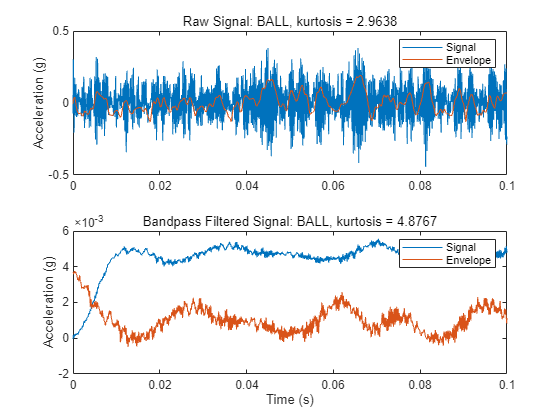

% Design bandpass filter
bpf = designfilt('bandpassfir', 'FilterOrder', 200, 'CutoffFrequency1', fc_BALL-bw_BALL/2 + 1, ...
    'CutoffFrequency2', fc_BALL + bw_BALL/2 - 1, 'SampleRate', fs);

% Apply bandpass filter
xBALLBpf = filter(bpf, xBall);

% Calculate Kurtosis
kurtBALL = kurtosis(xBall);
kurtBALLBpf = kurtosis(xBALLBpf);

% Apply bandpass filtered envelope spectrum
[pEnvBALLBpf, fEnvBALLBpf, xEnvBALLBpf, tEnvBpfBALL] = envspectrum(xBall, fs, ...
    'FilterOrder', 200, 'Band', [(fc_BALL-bw_BALL/2)/fs (fc_BALL+bw_BALL/2)/fs]);

figure
subplot(2, 1, 1)
plot(T_BALL(1:121410), xBall, tEnvBALL, xEnvBALL)
ylabel('Acceleration (g)')
title(['Raw Signal: BALL, kurtosis = ', num2str(kurtBALL)])
xlim([0 0.1])
legend('Signal', 'Envelope')

subplot(2, 1, 2)
plot(T_BALL(1:121410), xBALLBpf, tEnvBpfBALL, xEnvBALLBpf)
ylabel('Acceleration (g)')
xlim([0 0.1])
xlabel('Time (s)')
title(['Bandpass Filtered Signal: BALL, kurtosis = ', num2str(kurtBALLBpf)])
legend('Signal', 'Envelope')

#### 6-2. Inner race fault bandpass filter applying

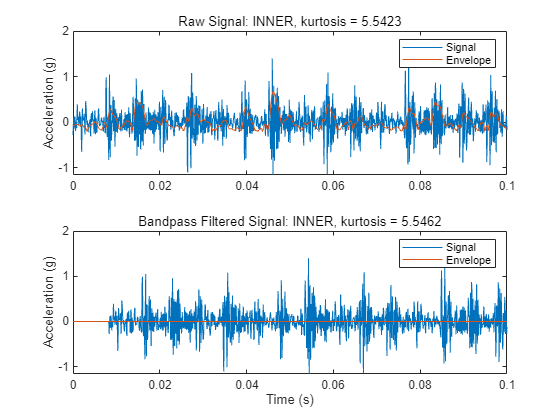

% Design bandpass filter
bpf = designfilt('bandpassfir', 'FilterOrder', 200, 'CutoffFrequency1', (fc_INNER - bw_INNER/2 + 1), ...
    'CutoffFrequency2', (fc_INNER + bw_INNER/2 - 1), 'SampleRate', fs);

% Apply bandpass filter
xINNERBpf = filter(bpf, xInner);

% Calculate Kurtosis
kurtINNER = kurtosis(xInner);
kurtINNERBpf = kurtosis(xINNERBpf);

% Apply bandpass filtered envelope spectrum
[pEnvINNERBpf, fEnvINNERBpf, xEnvINNERBpf, tEnvBpfINNER] = envspectrum(xInner, fs, ...
    'FilterOrder', 200, 'Band', [(fc_INNER-bw_INNER/2)/fs (fc_INNER+bw_INNER/2)/fs]);

figure;
subplot(2, 1, 1)
plot(T_INNER(1:121991), xInner, tEnvINNER, xEnvINNER)
ylabel('Acceleration (g)')
title(['Raw Signal: INNER, kurtosis = ', num2str(kurtINNER)])
xlim([0 0.1])
legend('Signal', 'Envelope')

subplot(2, 1, 2)
plot(T_INNER(1:121991), xINNERBpf, tEnvBpfINNER, xEnvINNERBpf)
ylabel('Acceleration (g)')
xlim([0 0.1])
xlabel('Time (s)')
title(['Bandpass Filtered Signal: INNER, kurtosis = ', num2str(kurtINNERBpf)])
legend('Signal', 'Envelope')

#### 6-3. Normal fault bandpass filter applying

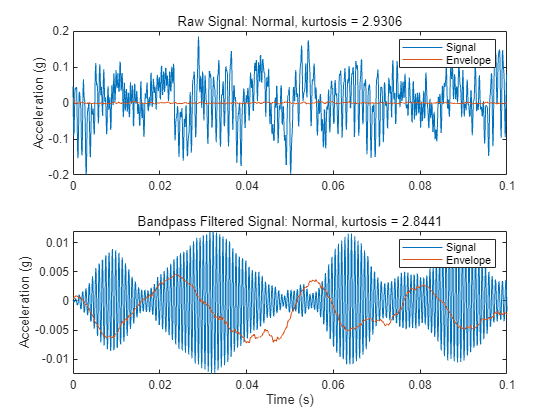

% Design bandpass filter
bpf = designfilt('bandpassfir', 'FilterOrder', 200, 'CutoffFrequency1', fc_NORMAL-bw_NORMAL/2, ...
    'CutoffFrequency2', fc_NORMAL+bw_NORMAL/2, 'SampleRate', fs);

% Apply bandpass filter
xNORMALBpf = filter(bpf, xNormal);

% Calculate Kurtosis
kurtNORMAL = kurtosis(xNormal);
kurtNORMALBpf = kurtosis(xNORMALBpf);

% Apply bandpass filtered envelope spectrum
[pEnvNORMALBpf, fEnvNORMALBpf, xEnvNORMALBpf, tEnvBpfNORMAL] = envspectrum(xNormal, fs, ...
    'FilterOrder', 200, 'Band', [fc_NORMAL-bw_NORMAL/2 fc_NORMAL+bw_NORMAL/2]);

figure;
subplot(2, 1, 1)
plot(T_NORMAL(1:483903), xNormal, tEnvNORMAL, xEnvNORMAL)
ylabel('Acceleration (g)')
title(['Raw Signal: Normal, kurtosis = ', num2str(kurtNORMAL)])
xlim([0 0.1])
legend('Signal', 'Envelope')

subplot(2, 1, 2)
plot(T_NORMAL(1:483903), xNORMALBpf, tEnvBpfNORMAL, xEnvNORMALBpf)
ylabel('Acceleration (g)')
xlim([0 0.1])
xlabel('Time (s)')
title(['Bandpass Filtered Signal: Normal, kurtosis = ', num2str(kurtNORMALBpf)])
legend('Signal', 'Envelope')

#### 6-4. Outer race fault bandpass filter applying

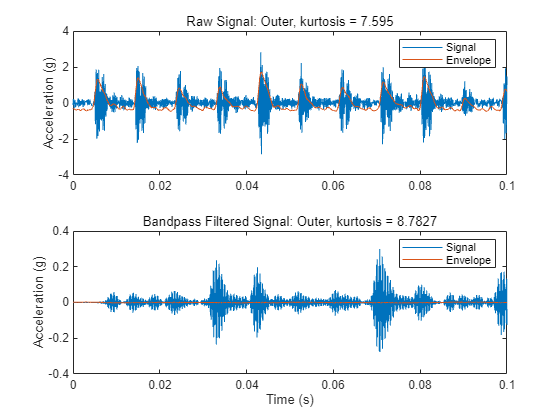

% Design bandpass filter
bpf = designfilt('bandpassfir', 'FilterOrder', 200, 'CutoffFrequency1', fc_OUTER-bw_OUTER/2 + 1, ...
    'CutoffFrequency2', fc_OUTER+bw_OUTER/2 - 1, 'SampleRate', fs);

% Apply bandpass filter
xOUTERBpf = filter(bpf, xOuter);

% Calculate Kurtosis
kurtOUTER = kurtosis(xOuter);
kurtOUTERBpf = kurtosis(xOUTERBpf);

% Apply bandpass filtered envelope spectrum
[pEnvOUTERBpf, fEnvOUTERBpf, xEnvOUTERBpf, tEnvBpfOUTER] = envspectrum(xOuter, fs, ...
    'FilterOrder', 200, 'Band', [(fc_OUTER-bw_OUTER/2)/fs (fc_OUTER+bw_OUTER/2)/fs]);

figure;
subplot(2, 1, 1)
plot(T_OUTER(1:122426), xOuter, tEnvOUTER, xEnvOUTER)
ylabel('Acceleration (g)')
title(['Raw Signal: Outer, kurtosis = ', num2str(kurtOUTER)])
xlim([0 0.1])
legend('Signal', 'Envelope')

subplot(2, 1, 2)
plot(T_OUTER(1:122426), xOUTERBpf, tEnvBpfOUTER, xEnvOUTERBpf)
ylabel('Acceleration (g)')
xlim([0 0.1])
xlabel('Time (s)')
title(['Bandpass Filtered Signal: Outer, kurtosis = ', num2str(kurtOUTERBpf)])
legend('Signal', 'Envelope')

## **7. Feature Analysis and Comparison  **

#### 7-1. Discussion about Time Domain Feature Extraction

Time domain에서의 feature의 경우 mean, std, rms, sra, aav, energy, peak, ppv, if, sf, cf, mf, sk, kt

Discussion goes here

%%% YOUR CODE GOES HERE
